# Illustrate sensor aliasing using a monochrome sensor

When the acuity of the lens exceeds the sampling rate of the sensor, aliasing patterns emerge. These are low frequency patterns in the sensor response that are caused by the high frequency patterns in the original image but under-sampled by the sensor.

To protect against aliasing, you can use a lens that does not pass the high frequency terms.

The aliasing artifacts illustrated here are for a monochrome sensor. When the same problem arises from a color CFA, the artifacts emerge as unwanted colors (chromatic aliasing).

Copyright Imageval Consulting, LLC, 2016

ieInit

## Set up a sweep frequency

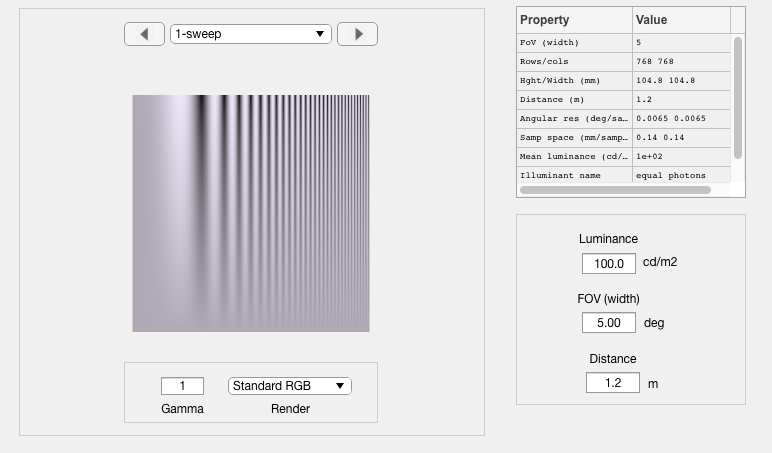

fov = 5;
scene = sceneCreate('sweep frequency',768,30);
scene = sceneSet(scene,'fov',fov);
ieAddObject(scene); sceneWindow;

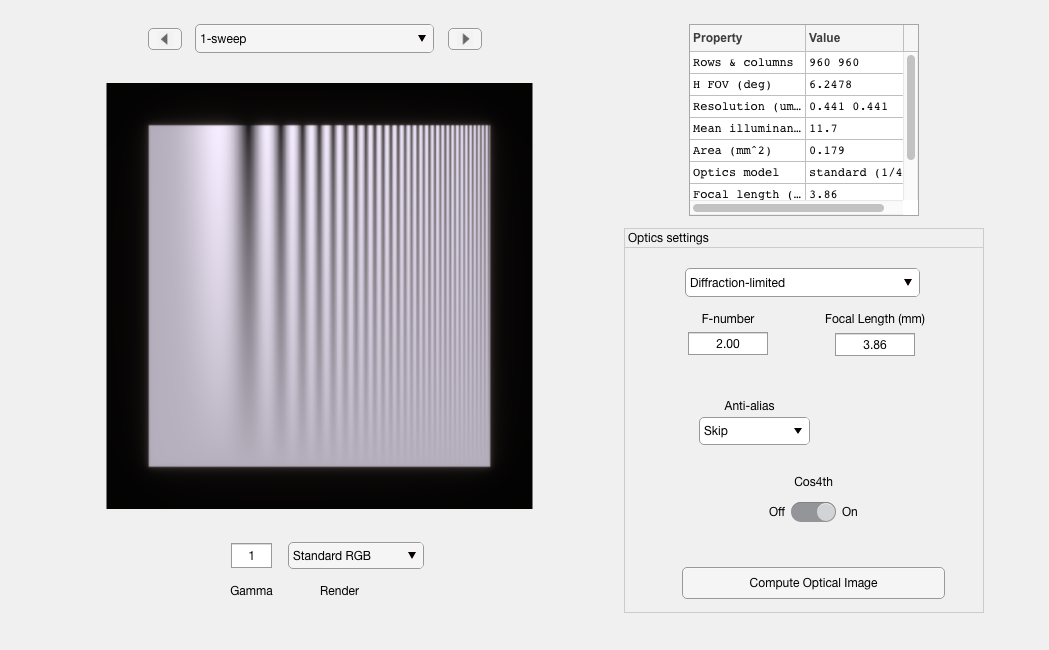


% Set up a high acuity lens
oi = oiCreate('diffraction limited');
oi = oiSet(oi,'optics fnumber', 2);
oi = oiCompute(oi,scene);
ieAddObject(oi); oiWindow;

## We use a small pixel size and see the scene come through correctly

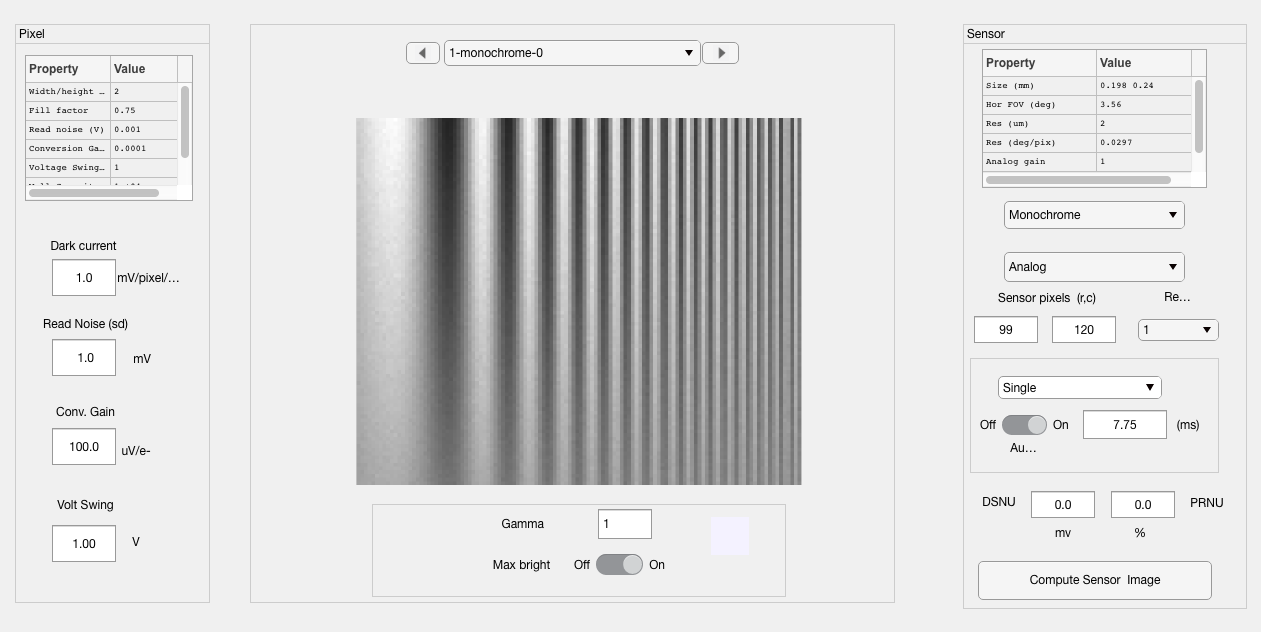

sensor = sensorCreate('monochrome');
sensor = sensorSetSizeToFOV(sensor,fov,oi);

% Set a two micron pixel
sensor = sensorSet(sensor,'pixel size constant fill factor',2e-6);
sensor = sensorCompute(sensor,oi);
ieAddObject(sensor);
sensorWindow;

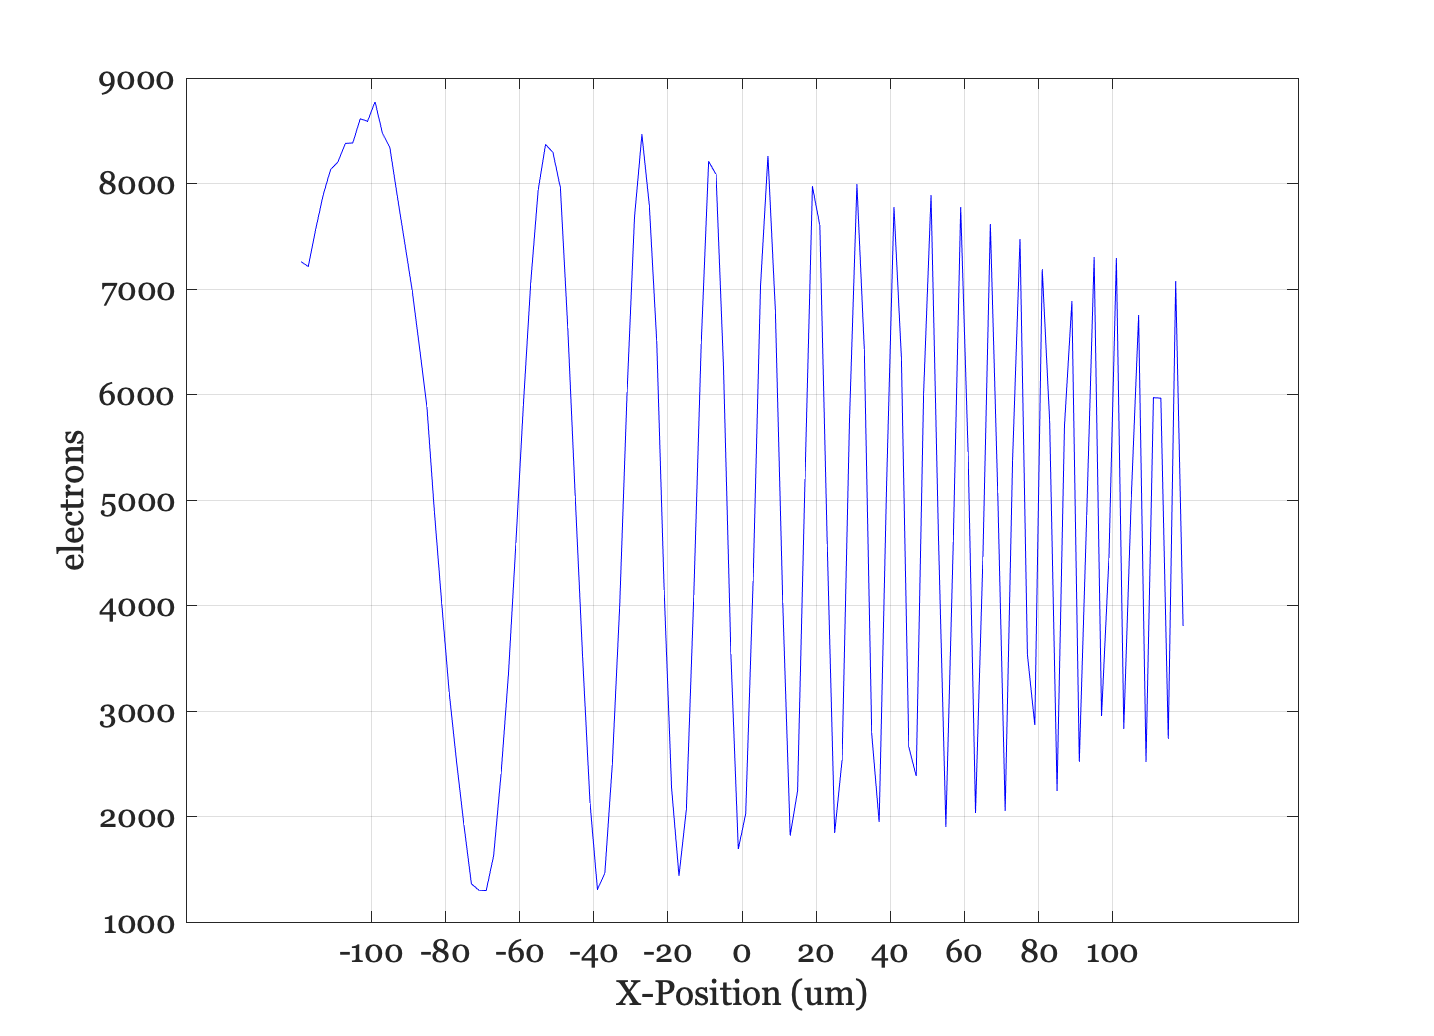


sensorPlot(sensor,'electrons hline',[5 1]);

## Make the sensor pixel under-sample by creating a large pixel.

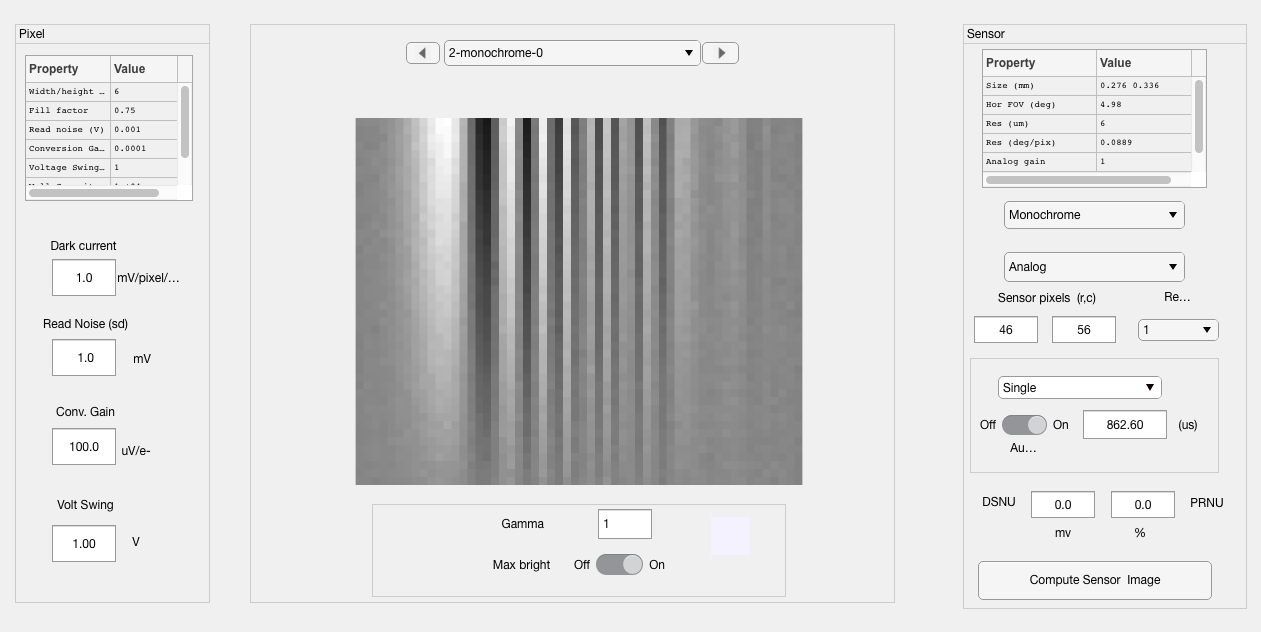

% Now, notice the aliased signal on the right.  The scene and oi are high
% spatial frequency, but the sensor capture appears to be low spatial
% frequency.
sensor = sensorSet(sensor,'pixel size constant fill factor',6e-6);
sensor = sensorSetSizeToFOV(sensor,fov,oi);
sensor = sensorCompute(sensor,oi);
ieAddObject(sensor); sensorWindow;

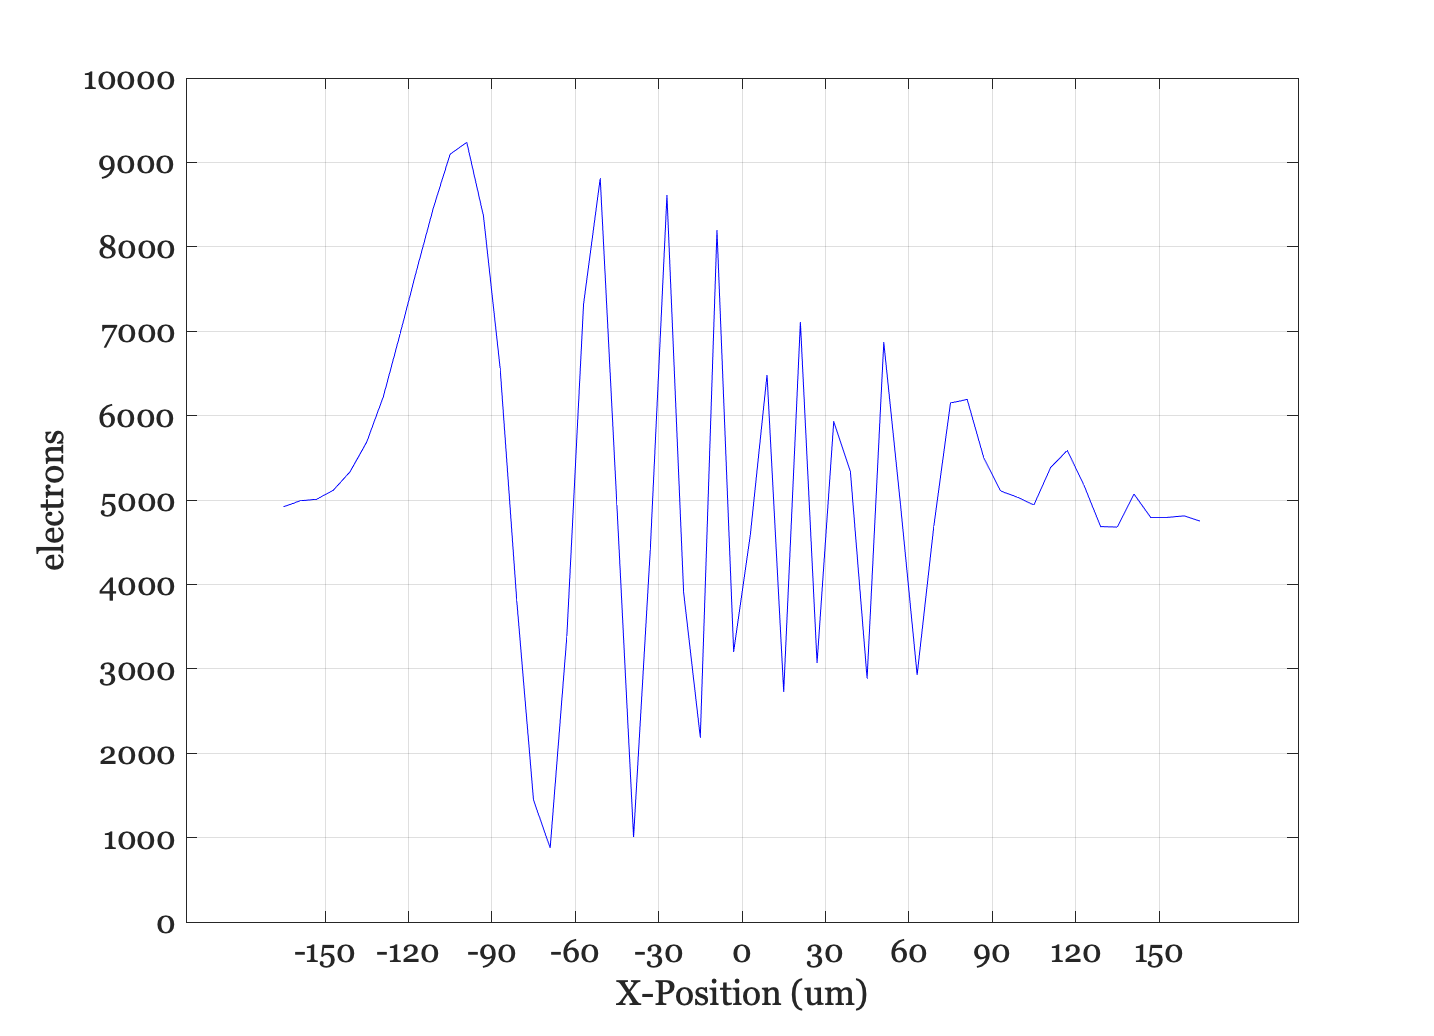


sensorPlot(sensor,'electrons hline',[5 1]);

## Now, protect from aliasing by using a blurry lens

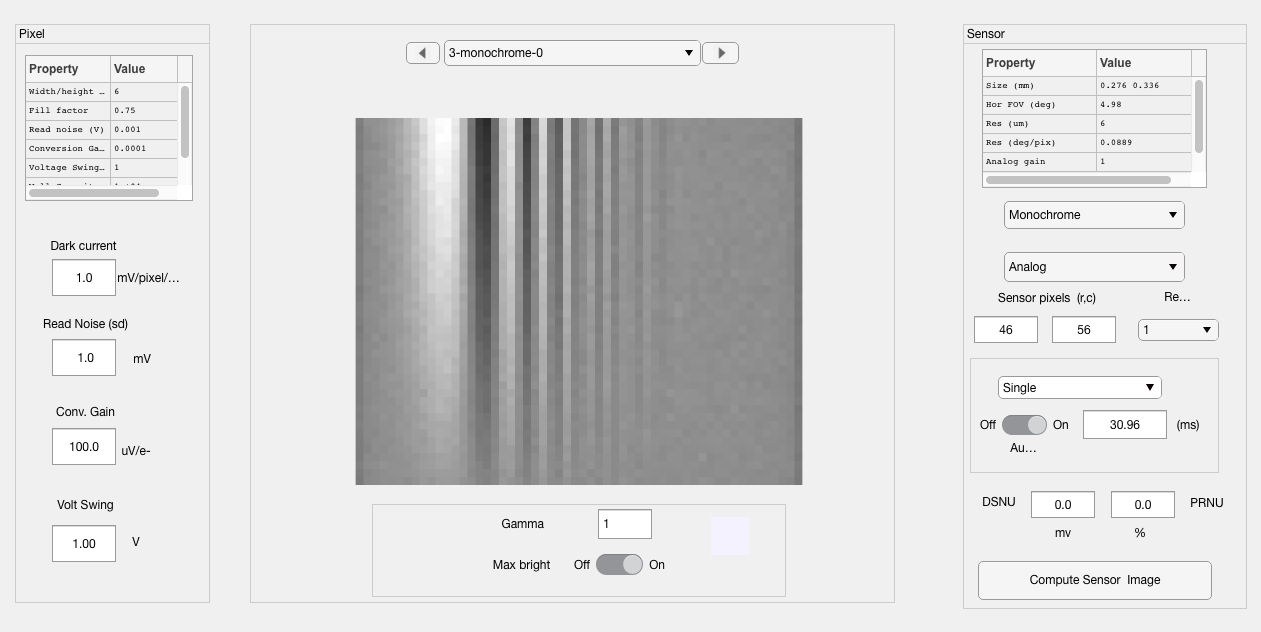

oi = oiSet(oi,'optics fnumber', 12);
oi = oiCompute(oi,scene);
sensor = sensorCompute(sensor,oi);
ieAddObject(sensor); sensorWindow;

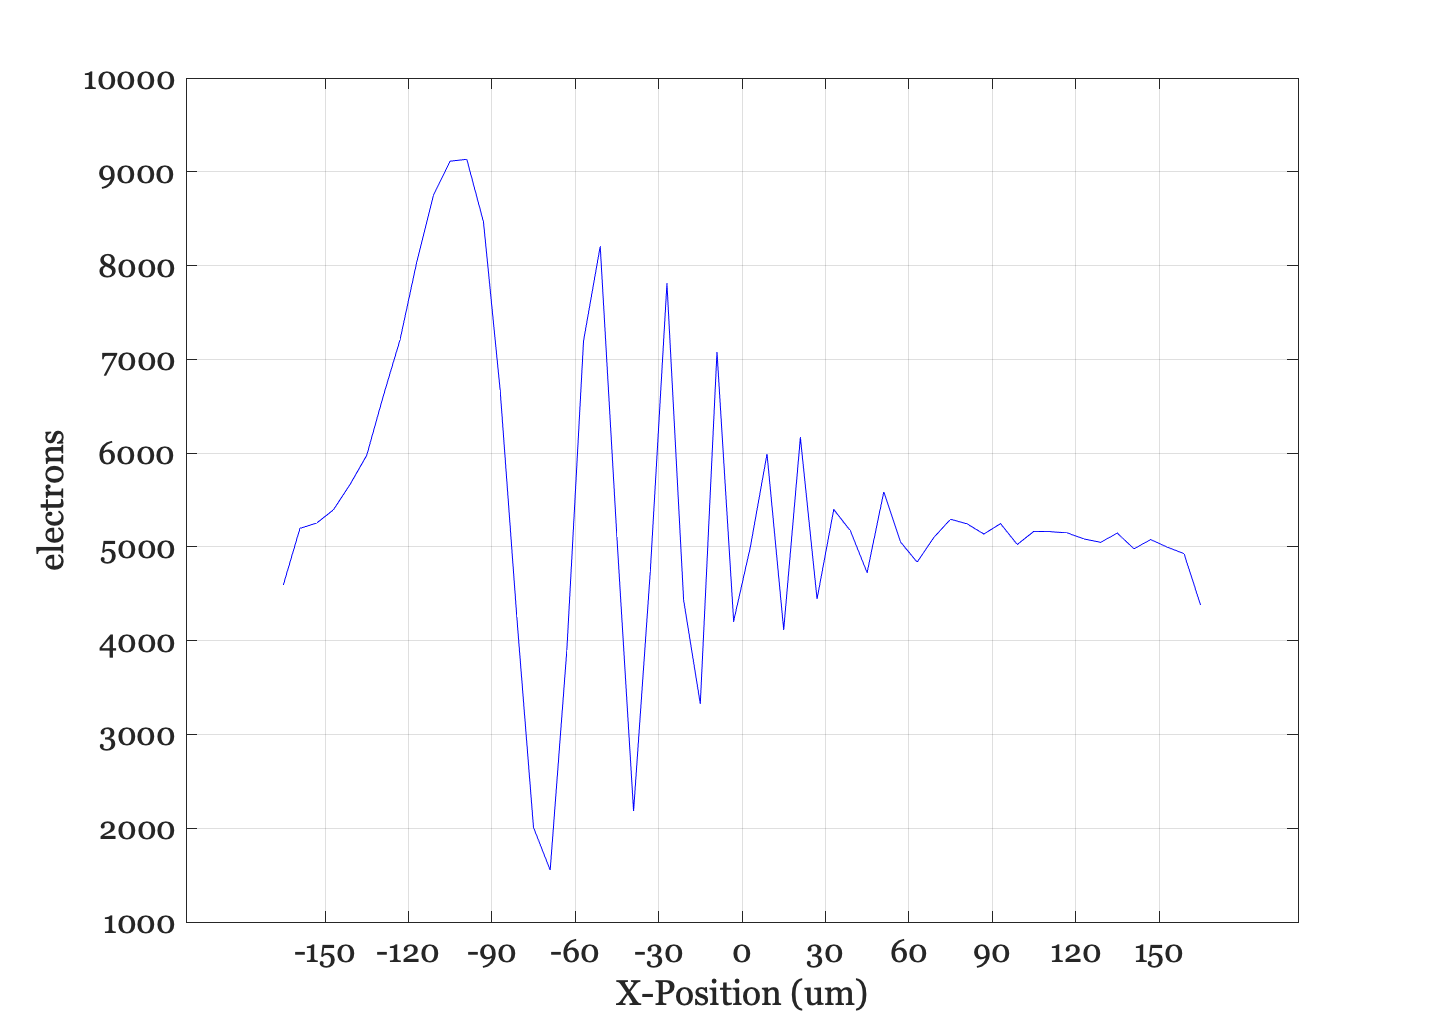

ans = struct with fields:
     pos: [1×56 double]
    data: [1×56 single]



sensorPlot(sensor,'electrons hline',[5 1])

## This is what aliasing looks like for the slanted bar target

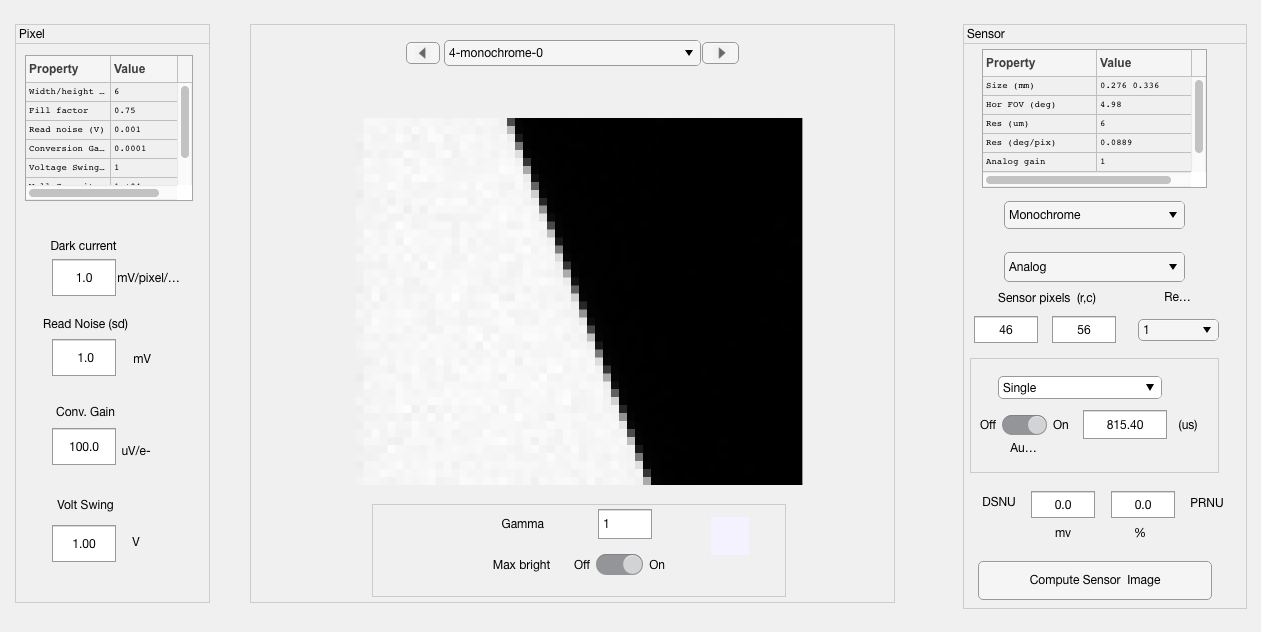

% This is why people sometimes say 'aliasing' creates 'jaggies'
scene = sceneCreate('slanted bar',1024);
scene = sceneSet(scene,'fov',fov);

oi = oiSet(oi,'optics fnumber', 2);
sensor = sensorSet(sensor,'pixel size constant fill factor',6e-6);
sensor = sensorSetSizeToFOV(sensor,fov,oi);
oi = oiCompute(oi,scene);
sensor = sensorCompute(sensor,oi);
ieAddObject(sensor); sensorWindow;

## If we protect against aliasing

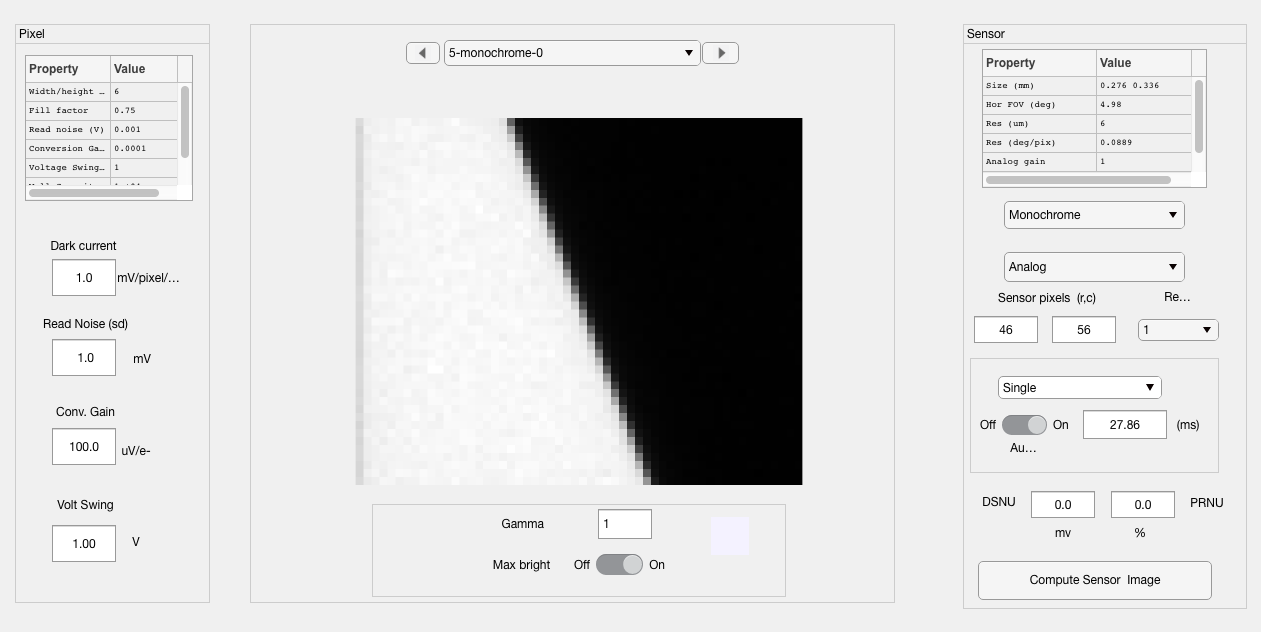

oi = oiSet(oi,'optics fnumber', 12);
oi = oiCompute(oi,scene);
sensor = sensorCompute(sensor,oi);
ieAddObject(sensor); sensorWindow;